clc 
clear all
c = [0
-0.003991957
0.685180531
1.086684771
1.370421552
1.589635125
2.649778226
3.123566845
3.424321285
3.641148229
3.808483054
4.303303993
4.560998839
4.724170259
4.838169014
4.922801761
4.988348785
5.040711762]

c =          0
   -0.0040
    0.6852
    1.0867
    1.3704
    1.5896
    2.6498
    3.1236
    3.4243
    3.6411



t = [69.52333333
57.08333333
52.39
49.18
47.53666667
46.06
39.3
35.57666667
33.54666667
32.17
30.81
28.69333333
28.25666667
28.02
28.47
27.96
28.17333333
28.24]

t =    69.5233
   57.0833
   52.3900
   49.1800
   47.5367
   46.0600
   39.3000
   35.5767
   33.5467
   32.1700



y_func= @(p,c) p(1).*c + p(2);
guess = [0.35 5e5]

guess = 	1.0e+05 *

    0.0000    5.0000


y_model=fitnlm(c(5:12),t(5:12),y_func,guess)

y_model = Nonlinear regression model:
    y ~ p1*c + p2

Estimated Coefficients:
          Estimate      SE        tStat       pValue  
          ________    _______    _______    __________

    p1     -6.647     0.14791    -44.939    8.1318e-09
    p2     56.579     0.46537     121.58    2.0879e-11


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.411
R-Squared: 0.997,  Adjusted R-Squared 0.997
F-statistic vs. constant model: 2.02e+03, p-value = 8.13e-09

y_model2=fitnlm(c(13:18),t(13:18),y_func,guess)

y_model2 = Nonlinear regression model:
    y ~ p1*c + p2

Estimated Coefficients:
          Estimate       SE        tStat        pValue  
          _________    _______    ________    __________

    p1    -0.067325    0.50993    -0.13203       0.90134
    p2       28.513     2.4725      11.532    0.00032287


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 0.204
R-Squared: 0.00434,  Adjusted R-Squared -0.245
F-statistic vs. constant model: 0.0174, p-value = 0.901

fit_y=feval(y_model,c)

fit_y =    56.5786
   56.6051
   52.0241
   49.3553
   47.4693
   46.0122
   38.9654
   35.8161
   33.8170
   32.3757


fit_y2=feval(y_model2,c)

fit_y2 =    28.5129
   28.5132
   28.4668
   28.4398
   28.4206
   28.4059
   28.3345
   28.3026
   28.2824
   28.2678


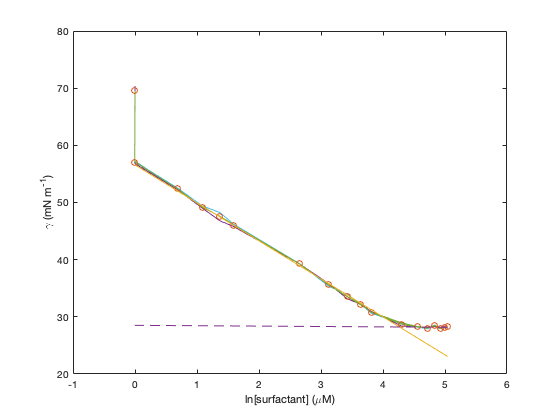

plot(c,t,'o',c,fit_y,'-',c,fit_y2,'--')
ylabel('\gamma (mN m^-^1)')
xlabel('ln[surfactant] (\muM)')


clc
clear all

x = [0
9.96E-01
1.98E+00
2.96E+00
3.94E+00
4.90E+00
1.42E+01
2.27E+01
3.07E+01
3.81E+01]' %uM 4.5082E-05

x =          0    0.9960    1.9800    2.9600    3.9400    4.9000   14.2000   22.7000   30.7000   38.1000



St = [69.52333333
57.08333333
52.39
49.18
47.53666667
46.06
39.3
35.57666667
33.54666667
32.17]' %mN/m 30.81

St =    69.5233   57.0833   52.3900   49.1800   47.5367   46.0600   39.3000   35.5767   33.5467   32.1700



Y = St*10^-3 %N/m

Y =     0.0695    0.0571    0.0524    0.0492    0.0475    0.0461    0.0393    0.0356    0.0335    0.0322



S = @(p,x) p(1)-((8.314*298)./p(2))*log(1+p(3).*x)

S = function_handle with value:
    @(p,x)p(1)-((8.314*298)./p(2))*log(1+p(3).*x)


guess = [.0695 1 1]

guess =     0.0695    1.0000    1.0000


fit = fitnlm(x,St,S,guess)

fit = Nonlinear regression model:
    y ~ p1 - ((8.314*298)/p2)*log(1 + p3*x)

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    p1     69.572     0.32851    211.78    1.3815e-14
    p2     351.56      5.4192    64.872     5.434e-11
    p3     5.3588     0.44853    11.948    6.5481e-06


Number of observations: 10, Error degrees of freedom: 7
Root Mean Squared Error: 0.329
R-Squared: 0.999,  Adjusted R-Squared 0.999
F-statistic vs. constant model: 5.66e+03, p-value = 5.88e-12

fity = feval(fit,x)

fity =    69.5722   56.5594   52.2926   49.6628   47.7520   46.2780   38.9509   35.6792   33.5666   32.0529


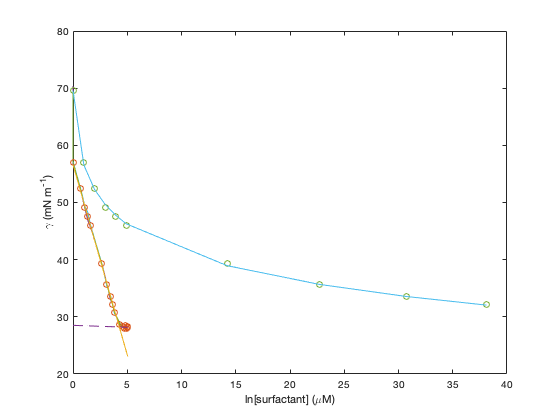

plot(x,St,'o',x,fity,'-')

%Angstrom

clc
clear all
syms w sw Av A sA

A=w./Av

$$A = \frac{w}{\mathrm{Av}}$$

double(subs(A,{w,Av},{3.5147E25,6.023E23}))

ans = 58.3546

sA = sqrt(sw^2*diff(A,w)^2)

$$sA = \sqrt{\frac{{\mathrm{sw}}^{2}}{{\mathrm{Av}}^{2}}}$$

double(subs(sA,{w,Av,sw},{3.5147*10^25,6.023*10^23,3.0458*10^23}))

ans = 0.5057

%G - Free energy

clc 
clear all

syms G sG R T sK K

G=-R*T*log(K)

$$G = -R\,T\,\log\left(K\right)$$

sG=sqrt(sK^2*diff(G,K)^2)

$$sG = \sqrt{\frac{R^{2}\,T^{2}\,{\mathrm{sK}}^{2}}{K^{2}}}$$

double(subs(G,{R,T,K},{0.008315,298,5.352E6}))

ans = -38.3896

double(subs(sG,{R,T,K,sK},{0.008314,298,5.352E6,29.198}))

ans = 1.3516e-05